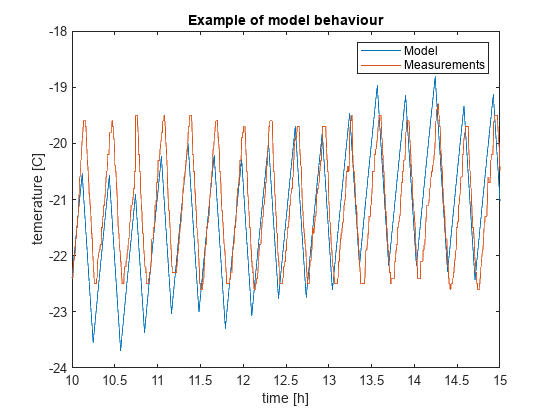

clear
load data2.mat
n=length(data.CzasLokalnyUTC0000);

T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);

h10th=10*60*60*fs;
h15th=15*60*60*fs;

t=T*(h10th:h15th);
X=X';
X=X(:,h10th:h15th);

X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,0;-5,0];
for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end
x=X(2,:);
y=X_filtered(3,:);
Ta=X_filtered(1,:);

R=-99;
C=-98;
G=-1.07;
x0=y(1);


y1=ModelFunction(-x',Ta',G,R,C,t,x0);

plot(t/(60*60),y1,'-'); hold on
plot(t/(60*60),y,'-');hold off
title('Example of model behaviour')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Model','Measurements')

e=rmse(y,y1')

e = 0.8007

out = ga(@costFuncLocal,3,[],[],[],[],[0.001 1 1],[])

Optimization terminated: maximum number of generations exceeded.


out =     2.7606   38.7790   82.6613


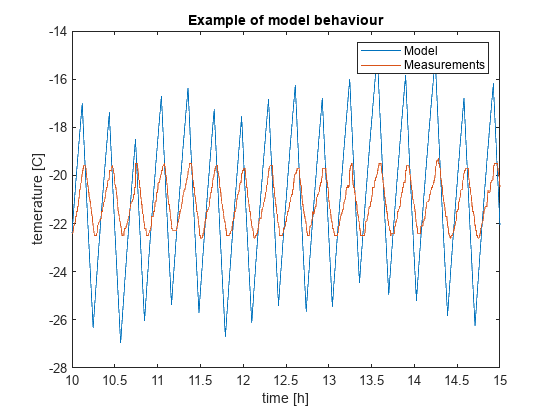


y1=ModelFunction(-x',Ta',out(1),out(2),out(3),t,x0);

plot(t/(60*60),y1,'-'); hold on
plot(t/(60*60),y,'-');hold off
title('Example of model behaviour')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Model','Measurements')

e1=rmse(y,y1')

e1 = 2.1285

[y2,params]=GATrain(x, Ta, t, x0, y);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


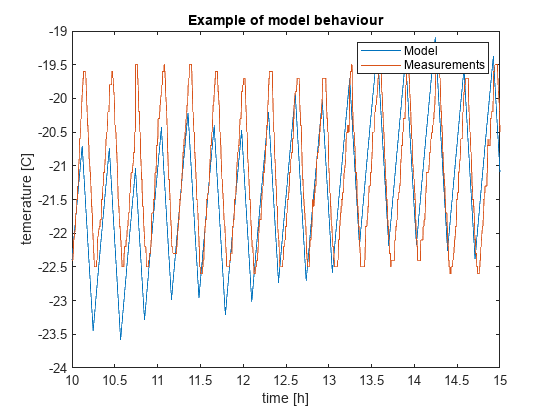

plot(t/(60*60),y2,'-'); hold on
plot(t/(60*60),y,'-');hold off
title('Example of model behaviour')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Model','Measurements')

e2=rmse(y,y2')

e2 = 0.7932

function cost = costFuncLocal(params)

load optPacket.mat

cost = costFunction(-x',Ta',params(1),params(2),params(3),t,x0,y);

end